- **1계 선형 상미분방정식의 일반형**


$$y' + p(x)y = r(x)$$


- 위와 같은 형태의 미분방정식이 1계 선형 상미분방정식

- 비선형 상미분방정식은 이와 같은 형태로 표현되지 않는 경우

- **제차와 비제차**


$$y' + p(x)y = r(x)$$


- $r\left(x\right)$는 입력값으로 $y$를 변화시키는 외부요인

- $r(x) = 0$일 때, **제차**(Homogeneous, 동차)

- $r(x) \neq 0$일 때, **비제차**(Nonhomogeneous, 비동차)

- **제차방정식**은 해가 특정 조건을 만족하며, 일반적으로 지수함수 형태의 해를 가짐.

- **비제차방정식**은 제차방정식의 해에 특수해를 더한 형태로 표현됨.

- $y\prime +2y=0$은 제차방정식의 예시로 해는 $y = Ce^{-2x}$

- $y' + 2y = 3$은 비제차방정식의 예시로 해는 $y = Ce^{-2x} + \frac{3}{2}$

**1계 선형 상미분방정식**


$$y'(t) + p(t)y(t) = g(t)$$


- $y'(t)$: 함수 $y(t)$의 1계 도함수

- $p(t)$: 독립 변수 $t$의 함수로, 미분 방정식의 계수

- $g(t)$: 독립 변수 $t$의 함수로, 비동차항을 나타냄

**해법**

- **일반해를 찾는 방법**:

- 동차 방정식을 먼저 풀이: $y'(t) + p(t)y(t) = 0$

- 동차 방정식의 해는 $y_h(t) = C e^{-\int p(t) \, dt}$

- 비동차 방정식의 특수해 $y_p(t)$를 찾음

- 전체 일반해: $y(t) = y_h(t) + y_p(t)$

- **적분 인자를 이용한 해법**:

- 적분 인자 $\mu(t) = e^{\int p(t) \, dt}$를 사용하여 미분 방정식을 풀 수 있음

- 미분 방정식에 $\mu(t)$를 곱한 후 정리하면 $y(t)$에 대해 직접적인 적분을 통해 해를 구할 수 있음

**인구 모델링 예시 **

**1. 지수 성장 모델**

- 지수 성장 모델은 일정한 비율로 인구가 증가하는 상황을 나타냄.

- 미분방정식으로 표현하면 다음과 같음.


$$\frac{dP(t)}{dt} = r \cdot P(t)dt$$


- 여기서

- $P(t)$: 시간 $t$에서의 인구

- $r$: 성장률 (고정된 값)

**초기 조건**

- 초기 인구 $P(0) = P_0$

**해**

- 이 미분방정식의 해는 다음과 같음.


$$P(t) = P_0 \cdot e^{rt}$$


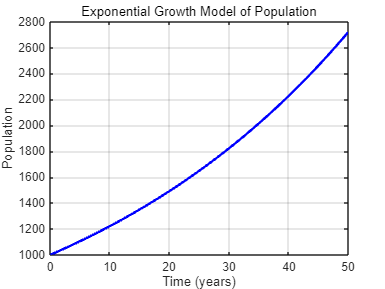

% 인구 모델링을 위한 MATLAB 코드

% 초기 인구
P0 = 1000; % 예: 1000명

% 성장률
r = 0.02; % 예: 2% 성장률

% 시간 범위
t = 0:1:50; % 0년부터 50년까지

% 인구 계산
P = P0 * exp(r * t);

% 그래프 그리기
figure;
plot(t, P, 'b-', 'LineWidth', 2);
xlabel('Time (years)');
ylabel('Population');
title('Exponential Growth Model of Population');
grid on;

- 시간에 따른 인구 변화가 지수적으로 증가

**2. RL 회로 해석**

- RL 회로는 저항기(R)와 인덕터(L)로 구성된 회로.

- Kirchhoff의 전압 법칙을 적용하면 다음과 같은 미분방정식이 유도됨.


$$L\frac{di(t)}{dt} + Ri(t) = V(t)$$


- $L$: 인덕턴스 (H)

- $R$: 저항 (Ω)

- $i(t)$: 시간 $t$에서의 전류 (A)

- $V(t)$: 시간 $t$에서의 전압 (V)

- 입력 전압이 일정한 경우, $V(t) = V_0$:


$$L\frac{di(t)}{dt} + Ri(t) = V_0$$


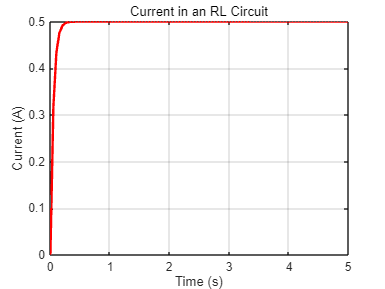

% RL 회로 해석을 위한 MATLAB 코드

% 회로 파라미터
L = 0.5; % 인덕턴스 (H)
R = 10; % 저항 (Ω)
V0 = 5; % 입력 전압 (V)

% 초기 조건 및 시간 범위
i0 = 0; % 초기 전류 (A)
t = linspace(0, 5, 100); % 시간 범위 (0 ~ 5초)

% RL 회로의 미분 방정식의 해
i = (V0 / R) * (1 - exp(-R * t / L));

% 그래프 그리기
figure;
plot(t, i, 'r-', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Current (A)');
title('Current in an RL Circuit');
grid on;

- 시간에 따른 RL 회로의 전류 변화가 지수적으로 증가하는 모습을 보여줌.

- 회로의 최종 전류는 $\frac{V_0}{R}$에 수렴.

- 초기에는 전류가 급격하게 증가하지만, 시간이 지남에 따라 점점 안정화되어 일정한 값에 도달함.

**3. 화학 반응 속도**

- 1차 반응의 경우 반응물 $A$가 시간에 따라 소모되는 속도는 다음과 같이 표현됨.


$$\frac{d[A]}{dt} = -k[A]dt$$


- $[A]$: 반응물 농도

- $k$: 반응 속도 상수

- 해는 다음과 같음:


$$[A](t) = [A]_0 e^{-kt}$$


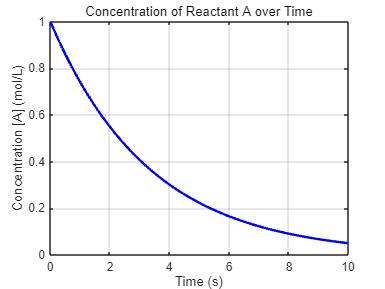

% 화학 반응 속도를 위한 MATLAB 코드

% 반응 파라미터
k = 0.3; % 반응 속도 상수 (1/s)
A0 = 1.0; % 초기 농도 (mol/L)

% 시간 범위
t = linspace(0, 10, 100); % 시간 범위 (0 ~ 10초)

% 화학 반응 속도의 해
A = A0 * exp(-k * t);

% 그래프 그리기
figure;
plot(t, A, 'b-', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Concentration [A] (mol/L)');
title('Concentration of Reactant A over Time');
grid on;

- 1차 반응에서 반응물 농도가 시간이 지남에 따라 지수적으로 감소하는 모습을 보여줌.

- 초기 농도에서 시작하여 점차적으로 감소하며, $t$가 커질수록 변화율이 감소.

- 이는 반응물이 소비됨에 따라 반응 속도가 느려지는 현상을 나타냄.

**1차 제차 선형 상미분 방정식 해법**

**1. ****1계 제차 선형 상미분방정식 해의 특징**

- 방정식:$y' + p(x)y = 0$

- 특징:

- 입력이 없을 때 해를 구하는 경우임.

- 오로지 시스템의 특성에 따라 해가 결정됨.

**2. ****1계 제차 선형 상미분방정식 해법**

- 해법 과정:

- 미분 방정식을 분리 변수법을 이용하여 다음과 같이 정리: 


$$\frac{dy}{y} = -p(x)dx$$


- 양변을 적분하여: 


$$\ln|y| = -\int p(x)dx + C$$



$$y = Ce^{-\int p(x)dx}$$


- 일반해:


$$y(x) = Ce^{-\int p(x)dx}$$


- 특수한 경우:

- $y > 0$ 또는 $y < 0$일 때 $y = Ce^{-\int p(x)dx}$

- $y(x) = 0$**은 자명한 해(Trivial Solution)**

**뉴턴의 냉각법칙**

- 식으로 표현하면 다음과 같음:$\frac{dT}{dt} = -k(T - T_{env})dt$

- $T(t)$: 시간 $t$에서의 물체의 온도

- $T_{env}$: 주변 환경의 온도 (상수)

- $k
$: 냉각 상수 (양의 값)

**1. 변수분리형 상미분 방정식으로 풀기**

- 방정식을 재배열하여 변수분리:$\frac{dT}{T - T_{env}} = -k \, $

- 양변을 적분:$\int \frac{1}{T - T_{env}} \, dT = \int -k \, dt$

- 적분 결과:$\ln |T - T_{env}| = -kt + C$

- 지수화하여 정리:


$$|T - T_{env}| = e^{-kt + C} $$


$T - T_{env} = Ce^{-kt$(여기서 $C$는 $e^C$로 치환)

- 최종 해:$T(t) = T_{env} + Ce^{-kt}$

- $C$: 초기 조건에 따라 결정되는 상수

- 초기 온도 $T(0) = T_0$이면 $C = T_0 - T_{env}$

**2. 비제차 선형 상미분방정식으로 풀기**

- 주어진 방정식:$\frac{dT}{dt} = -k(T - T_{env})dt$

- 이를 정리하면 비제차 선형 상미분방정식의 형태가 됨:$\frac{dT}{dt} + kT = kT_{env}$

- $\frac{dT}{dt} + p(t)T = g(t)$ 형태에서 $p(t) = k$이고 $g(t) = kT_{env}$

**풀이 과정**

- **동차 방정식의 일반해를 구함**:

- 먼저 동차 방정식: $\frac{dT_h}{dt} + kT_h = 0$

- 이 방정식의 해를 구하기 위해 $\frac{dT_h}{dt} = -kT_h$를 분리 변수법으로 풀면:


$$\frac{1}{T_h} dT_h = -k \, dt  $$



$$\int \frac{1}{T_h} dT_h = \int -k \, dt         $$



$$\ln |T_h| = -kt + C$$



$$T_h = C_1e^{-kt}$$


- 따라서 동차 방정식의 일반해는:$T_h(t) = C_1e^{-kt}$

- **특수해를 구함**:

- 비제차 방정식의 특수해 $T_p(t)$를 구함.

- 이 방정식의 특수해를 상수 함수 $T_p = T_{env}$로 가정:$\frac{dT_p}{dt} = 0$

- 이를 비제차 방정식에 대입:$kT_{env} = kT_{env}$

- 이 식이 성립하므로 $T_p = T_{env}$는 특수해가 될 수 있음.

- **전체 해를 구함**:

- 전체 해는 동차 방정식의 해와 비제차 방정식의 특수해의 합으로 표현:


$$T(t) = T_h(t) + T_p(t)     $$



$$T(t) = C_1e^{-kt} + T_{env}$$


- **초기 조건을 이용하여 상수 **$C_1$** 결정**:

- 초기 조건 $T(0) = T_0$를 이용하면:


$$T(0) = C_1e^{0} + T_{env} = T_0      $$



$$C_1 = T_0 - T_{env}$$


- **최종 해**:$T(t) = T_{env} + (T_0 - T_{env})e^{-kt}$

**결론**

- 두 방법 모두 동일한 해를 제공함:$T(t) = T_{env} + (T_0 - T_{env})e^{-kt}$

- 비제차 선형 상미분방정식의 해법을 사용하여도 뉴턴의 냉각법칙을 정확하게 풀 수 있음.

- 해는 다음과 같음:


$$T(t) = T_{env} + (T_0 - T_{env})e^{-kt}$$


- 이 결과는 시간이 지남에 따라 물체의 온도가 주변 온도 $T_{env}$에 지수적으로 수렴하는 것을 보여줌.

- 비제차 상미분방정식을 푸는 과정에서 동차해와 특수해를 찾는 방법이 사용됨.

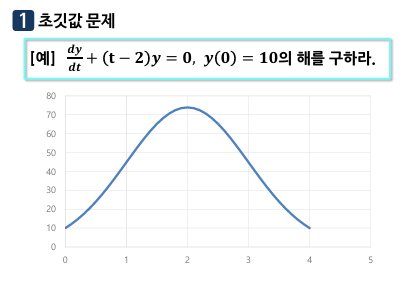

**1. 초깃값 문제**

- 주어진 미분방정식:$\frac{dy}{dt} + (t - 2)y = 0, \quad y(0) = 10$

- 이 문제는 1계 선형 상미분방정식의 형태로 주어짐.

- 초기 조건 $y(0) = 10$을 이용하여 해를 찾을 수 있음.

**풀이**

- **동차 방정식 형태**:

- 주어진 방정식은 이미 동차 방정식의 형태임.

- **적분 인자를 이용한 해법**:

- 적분 인자 $\mu(t)$는 $e^{\int (t - 2) \, dt} = e^{\frac{t^2}{2} - 2t}$로 계산됨.

- 방정식에 $\mu(t)$를 곱하여 정리함:


$$e^{\frac{t^2}{2} - 2t} \frac{dy}{dt} + (t-2)e^{\frac{t^2}{2} - 2t}y = 0\$$


- 이를 통해 적분 후 해를 구할 수 있음.

- **일반해**:


$$y(t) = Ce^{-\frac{t^2}{2} + 2t}$$


- 초기 조건 $y(0) = 10$을 적용하여 $C$ 값을 구함: 


$$y(0) = Ce^0 = C = 10$$


- **최종 해**: 


$$y(t) = 10e^{-\frac{t^2}{2} + 2t}$$


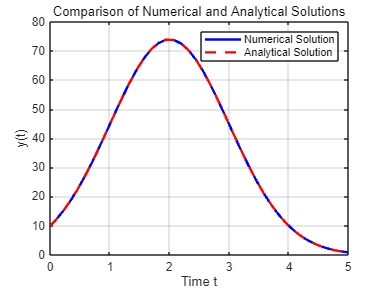

% 미분방정식 정의
ode = @(t, y) -(t - 2) .* y;

% 초기 조건
y0 = 10;

% 시간 범위
tspan = [0 5];

% ode45를 사용하여 미분방정식 풀기
[t, y] = ode45(ode, tspan, y0);

% 미분방정식의 변화량 계산
dydt = ode(t, y);

% 해석적 해 구하기 (수치해와 같은 시간 간격 사용)
y_analytic = y0 * exp(-t.^2 / 2 + 2 * t);

% 수치해와 해석적 해의 일치성 확인을 위한 2D 그래프 그리기
figure;
plot(t, y, 'b-', 'LineWidth', 2); % 수치해
hold on;
plot(t, y_analytic, 'r--', 'LineWidth', 2); % 해석적 해
xlabel('Time t');
ylabel('y(t)');
title('Comparison of Numerical and Analytical Solutions');
legend('Numerical Solution', 'Analytical Solution');
grid on;

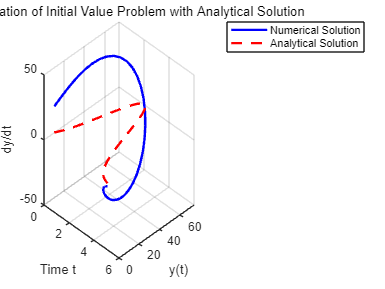


% 3D 그래프 그리기
figure;
plot3(t, y, dydt, 'b-', 'LineWidth', 2); % 수치해
hold on;
plot3(t, y_analytic, zeros(size(t)), 'r--', 'LineWidth', 2); % 해석적 해
xlabel('Time t');
ylabel('y(t)');
zlabel('dy/dt');
title('3D Visualization of Initial Value Problem with Analytical Solution');
legend('Numerical Solution', 'Analytical Solution');
grid on;
view(45, 30); % 그래프의 뷰 각도 조정

**해석적 해의 기울기와 수치적 기울기의 차이**

- 해석적 해를 이용하면 정확한 기울기를 계산할 수 있음.

- 반면에, 수치적 해에서는 각 시간 단계에서의 변화량을 기반으로 기울기를 계산하기 때문에 작은 차이가 발생할 수 있음.

- 특히, 3D 그래프에서는 이러한 기울기의 미세한 차이가 더욱 부각되어 보일 수 있음.

- 2차원에서는 해석적 해와 수치적 해의 $y(t)$값이 일치하지만, 3차원에서 나타나는 작은 차이는 수치 미분에 내재된 근사 오차 때문임.

- 이러한 오차는 수치적 방법의 특성상 불가피하며, 특히 미분 값의 정확도를 요구하는 3차원 시각화에서 더 두드러지게 나타날 수 있음.

- 하지만 이러한 차이는 대부분의 경우 무시할 수 있을 정도로 작으며, 수치적 해가 해석적 해의 거동을 전반적으로 잘 나타내고 있음을 의미함.

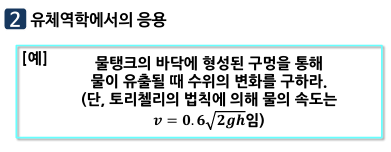

**2. 유체역학에서의 응용**

- 물탱크의 바닥에 형성된 구멍을 통해 물이 유출될 때 수위의 변화를 구하는 문제.

- 토리첼리의 법칙에 따르면 물의 속도는 $v = 0.6\sqrt{2gh$임.

**모델링**

- 유량 $Q$는 다음과 같이 표현됨:


$$Q = A \cdot v = A \cdot 0.6\sqrt{2gh}$$


- $A$: 구멍의 단면적

- $h$: 수위 높이

- $g$: 중력 가속도

- 물탱크의 부피 변화율은 수위의 변화율과 관련됨:


$$\frac{dV}{dt} = -A \cdot 0.6\sqrt{2gh}$$


- 부피 $V$와 수위 $h$는 탱크의 단면적$A_t$에 의해 다음과 같이 관계가 있음:


$$V = A_t h \quad \Rightarrow \quad \frac{dV}{dt} = A_t \frac{dh}{dt}$$


- $V$: 탱크 내부의 유체 부피 (m³)

- $A_t$: 탱크의 수직 단면적 (m²)

- $h$: 유체의 수위 또는 높이 (m)

**방정식**

- 따라서:


$$A_t \frac{dh}{dt} = -A \cdot 0.6\sqrt{2gh}$$


- 이를 정리하여 변수분리형 미분방정식으로 만들 수 있음:


$$\frac{dh}{\sqrt{h}} = -\frac{A \cdot 0.6\sqrt{2g}}{A_t} \, dt$$


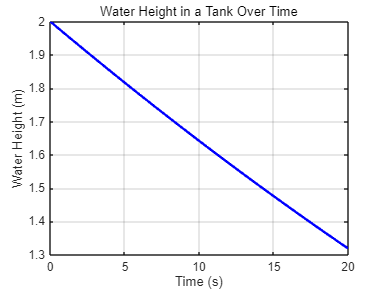

% 유체역학 문제를 위한 MATLAB 코드

% 상수 정의
A = 0.01; % 구멍의 단면적 (m^2)
A_t = 1; % 물탱크의 단면적 (m^2)
g = 9.81; % 중력 가속도 (m/s^2)
initial_height = 2; % 초기 수위 (m)

% 미분방정식 정의
ode = @(t, h) - (A / A_t) * 0.6 * sqrt(2 * g * h);

% 시간 범위
tspan = [0 20]; % 0에서 20초까지

% ode45를 사용하여 미분방정식 풀기
[t, h] = ode45(ode, tspan, initial_height);

% 그래프 그리기
figure;
plot(t, h, 'b-', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Water Height (m)');
title('Water Height in a Tank Over Time');
grid on;

유체역학 문제의 미분방정식은 다음과 같은 형태로 나타남:

$\frac{dh}{dt} = -\frac{A}{A_t} \cdot 0.6\sqrt{2gh}$�

이 미분방정식의 해를 구하기 위해 변수분리법을 적용할 수 있음. 일반적인 해는 다음과 같이 구할 수 있음:


$$\int \frac{1}{\sqrt{h}} \, dh = -\frac{A}{A_t} \cdot 0.6\sqrt{2g} \int dt$$



$$2\sqrt{h} = -\frac{A}{A_t} \cdot 0.6\sqrt{2g} \cdot t + C$$



$$\sqrt{h} = -\frac{A}{A_t} \cdot 0.3\sqrt{2g} \cdot t + \frac{C}{2}$$



$$h(t) = \left( -\frac{A}{A_t} \cdot 0.3\sqrt{2g} \cdot t + \frac{C}{2} \right)^2$$


초기 조건을 적용하면, $C$ 값은 초기 수위에 의해 결정됨.

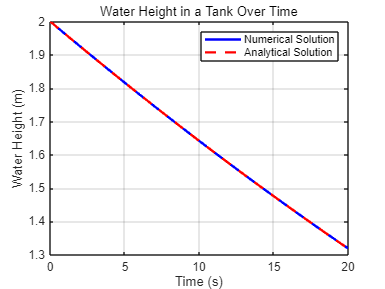

% 상수 정의
A = 0.01; % 구멍의 단면적 (m^2)
A_t = 1; % 물탱크의 단면적 (m^2)
g = 9.81; % 중력 가속도 (m/s^2)
initial_height = 2; % 초기 수위 (m)

% 미분방정식 정의
ode = @(t, h) - (A / A_t) * 0.6 * sqrt(2 * g * h);

% 시간 범위
tspan = [0 20]; % 0에서 20초까지

% ode45를 사용하여 미분방정식 풀기
[t, h] = ode45(ode, tspan, initial_height);

% 해석적 해 구하기
C = 2 * sqrt(initial_height);
h_analytic = (-(A / A_t) * 0.3 * sqrt(2 * g) * t + C / 2).^2;

% 수치해의 변화율 계산
dhdt_numerical = ode(t, h);

% 해석적 해의 변화율 계산
dhdt_analytic = - (A / A_t) * 0.6 * sqrt(2 * g * h_analytic);

% 2D 그래프 그리기
figure;
plot(t, h, 'b-', 'LineWidth', 2); % 수치해
hold on;
plot(t, h_analytic, 'r--', 'LineWidth', 2); % 해석적 해
xlabel('Time (s)');
ylabel('Water Height (m)');
title('Water Height in a Tank Over Time');
legend('Numerical Solution', 'Analytical Solution');
grid on;

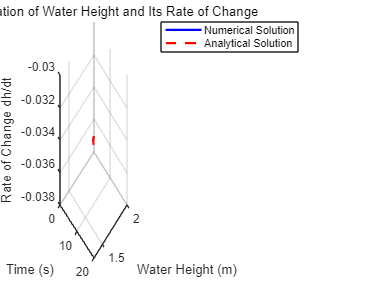


% 3D 그래프 그리기
figure;
plot3(t, h, dhdt_numerical, 'b-', 'LineWidth', 2); % 수치해 3D
hold on;
plot3(t, h_analytic, dhdt_analytic, 'r--', 'LineWidth', 2); % 해석적 해 3D
xlabel('Time (s)');
ylabel('Water Height (m)');
zlabel('Rate of Change dh/dt');
title('3D Visualization of Water Height and Its Rate of Change');
legend('Numerical Solution', 'Analytical Solution');
grid on;
view(45, 30); % 그래프의 뷰 각도 조정

**해석적 해 구하기**:

- $C = 2 \sqrt{h_0}$를 사용하여 해석적 해를 계산.

- $h(t) = \left( -\frac{A}{A_t} \cdot 0.3\sqrt{2g} \cdot t + \frac{C}{2} \right)^2$ 형태의 해석적 해를 구함.

**해석**:

- 수치적 해와 해석적 해는 전체적으로 잘 일치하며, 이를 통해 유체 역학 문제에 대한 모델링이 성공적으로 이루어졌음을 알 수 있습니다.

- 3D 그래프에서 보이는 미세한 불일치는 수치적 근사에 의한 것으로, 실제 해석적 모델링에서는 발생할 수 있는 일반적인 현상입니다.

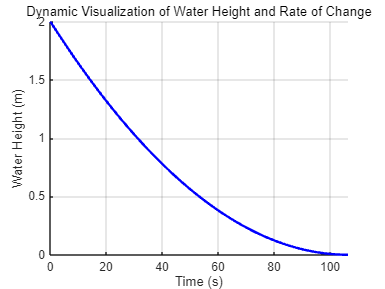

% 상수 정의
A = 0.01; % 구멍의 단면적 (m^2)
A_t = 1; % 물탱크의 단면적 (m^2)
g = 9.81; % 중력 가속도 (m/s^2)
initial_height = 2; % 초기 수위 (m)

% 해석적 해 수식
constantC = 2 * sqrt(initial_height);
h = @(t) (max(0, constantC/2 - (A/A_t) * 0.3 * sqrt(2*g) * t)).^2;
dhdt = @(t) - (A/A_t) * 0.6 * sqrt(2 * g * h(t)); % 수위 변화율

% 시간 범위
t_max = constantC/(2 * (A/A_t) * 0.3 * sqrt(2*g)); % 수위가 0이 되기 전까지의 시간
t = linspace(0, t_max, 500); % 시간 범위 설정

% 수위와 변화율 계산
h_values = h(t);
dhdt_values = dhdt(t);

% 동적 그래프 생성
figure;
hold on;
grid on;
xlabel('Time (s)');
ylabel('Water Height (m)');
zlabel('Rate of Change (dh/dt)');
title('Dynamic Visualization of Water Height and Rate of Change');
xlim([0, t_max]);
ylim([0, initial_height]);
zlim([min(dhdt_values), 0]);

% 애니메이션 그리기
for i = 1:length(t)
    plot3(t(1:i), h_values(1:i), dhdt_values(1:i), 'b', 'LineWidth', 2);
    drawnow;
end

hold off;

**문제**

전하가 $Q=10\mathrm{mC}$ 충전된 정전용량이 $C=50\mu F$ 인 축전기를 저항기에 연결함

전하량의 시간에 따른 변화량 $Q\left(t\right)$ 를 구하여라(단, 축전기 양단의 전압, $V$, 전하량 $Q$, 정전용량 $C$ 간에는 $Q=\mathrm{CV}$ 관계가 성립한다.)

**문제 설명**

- 초기 전하량 $Q_0 = 10 \text{mC}$

- 정전용량 $C = 50 \mu\text{F}$

- 저항 $R = 10 \text{k}\Omega$

**1계 제차 선형 상미분방정식 유도**

- 축전기의 전압과 전하량의 관계: $CV(t) = \frac{Q(t)}{C}$�

- 옴의 법칙에 따른 저항에 걸리는 전압: $V_R(t) = I(t) RV$

- 전류와 전하량의 관계: $dtI(t) = -\frac{dQ(t)}{dt}$ (방전이므로 음수)

회로에서의 전압에 대한 키르히호프의 법칙(KVL)을 적용하면:


$$V(t) = V_R(t)$$



$$(-dQ(t)dt)\frac{Q(t)}{C} = R \left(-\frac{dQ(t)}{dt}\right)$$


이를 정리하면:


$$\frac{dQ(t)}{dt} + \frac{1}{RC} Q(t) = 0$$


이것은 1계 제차 선형 상미분방정식의 표준 형태 $y'(t) + p(t) y(t) = 0$에 해당하며, 여기서:

$p(t) = \frac{1}{RC}$�**일반 해 풀이**

상미분방정식의 해는:

$Q(t) = Q_0 e^{-\frac{t}{RC}}$�

여기서:

- $Q_0$는 초기 전하량

- $\frac{1}{RC}$는 시스템의 시간 상수의 역수

**수식 정리**


$$Q(t) = Q_0 e^{-\frac{t}{RC}}$$


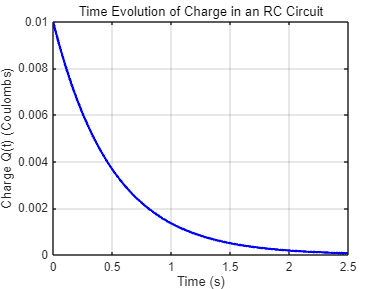

% 상수 정의
Q0 = 10e-3; % 초기 전하량 (Coulombs)
C = 50e-6; % 정전용량 (Farads)
R = 10e3; % 저항 (Ohms)

% 시간 상수 (RC)
tau = R * C;

% 시간 범위 설정
t = linspace(0, 5 * tau, 1000); % 최대 5*RC까지

% 1계 제차 선형 상미분방정식의 해
Q_t = Q0 * exp(-t / tau);

% 그래프 그리기
figure;
plot(t, Q_t, 'b', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Charge Q(t) (Coulombs)');
title('Time Evolution of Charge in an RC Circuit');
grid on;

�

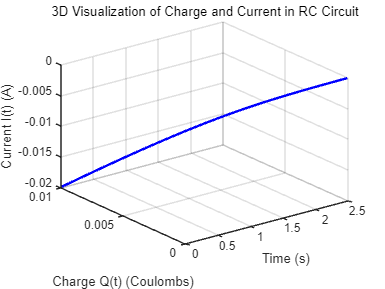


% 상수 정의
Q0 = 10e-3; % 초기 전하량 (Coulombs)
C = 50e-6; % 정전용량 (Farads)
R = 10e3; % 저항 (Ohms)

% 시간 상수 (RC)
tau = R * C;

% 시간 범위 설정
t_max = 5 * tau; % 최대 5*RC까지
t = linspace(0, t_max, 500); % 시간 벡터 생성

% 시간에 따른 전하량 변화
Q_t = Q0 * exp(-t / tau);
I_t = -Q0 / tau * exp(-t / tau); % 전류 I(t) = -dQ/dt

% 3D 그래프 생성
figure;
hold on;
grid on;
xlabel('Time (s)');
ylabel('Charge Q(t) (Coulombs)');
zlabel('Current I(t) (A)');
title('3D Visualization of Charge and Current in RC Circuit');
xlim([0, t_max]);
ylim([0, Q0]);
zlim([min(I_t), 0]);
view(3); % 3D 뷰 설정

% 3D 애니메이션 그리기
for i = 1:length(t)
    plot3(t(1:i), Q_t(1:i), I_t(1:i), 'b', 'LineWidth', 2);
    drawnow;
end

hold off;